# `Activity 6.2`

## `Compare Instruments Spectrograms`

fs = 44100;
[y1,~] = audioread("andean-flute-theme-low_fybeqsnu1.mp3");
[y2,~] = audioread("zo_-pripyati-gitara.mp3");
[y3,~] = audioread("cirk-barabannaya-drob-i-marsh_-silachi.mp3");
[y4,~] = audioread("jamaican-piano_mytjcqbd.mp3");
[y5,~] = audioread("violin-trill_mk15cun_.mp3");
[y6,~] = audioread("z_uk-truba.mp3");

#### `Create samples from audio files`

n_start = 20000;
n_samples = 10000;
n_stop = n_start+n_samples;
flute  = y1(n_start:n_stop,1);
gitar  = y2(n_start:n_stop,1);
drum   = y3(n_start:n_stop,1);
piano  = y4(n_start:n_stop,1);
violin = y5(n_start:n_stop,1);
trumpt = y6(n_start:n_stop,1);

window_size = 2048;
hop_size = window_size/2;

### `Visualization`

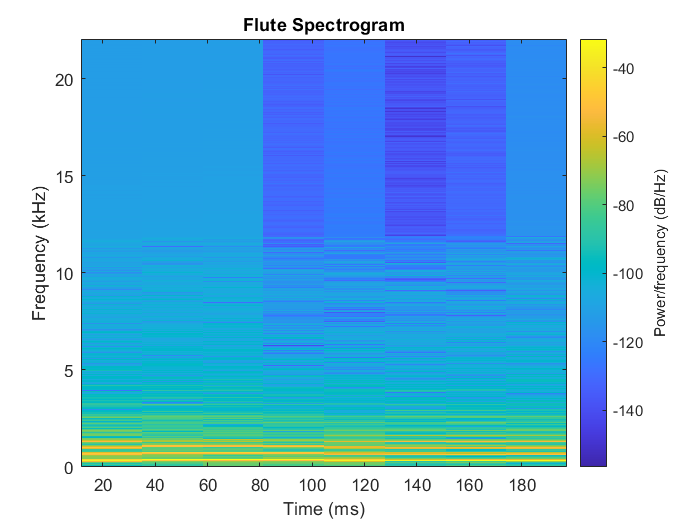

figure()
spectrogram(flute, window_size, hop_size,window_size,fs,'yaxis');
title('Flute Spectrogram')

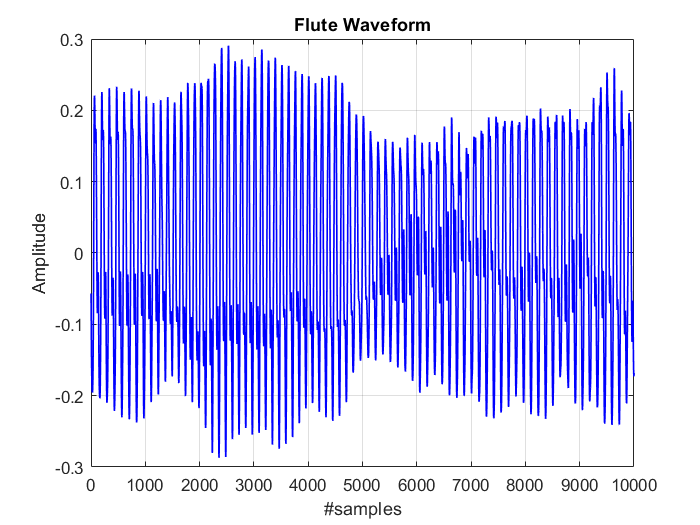

figure()
plot(flute,'b','LineWidth',1)
xlim([0,n_samples])
xlabel('#samples')
ylabel('Amplitude')
title('Flute Waveform')
grid on

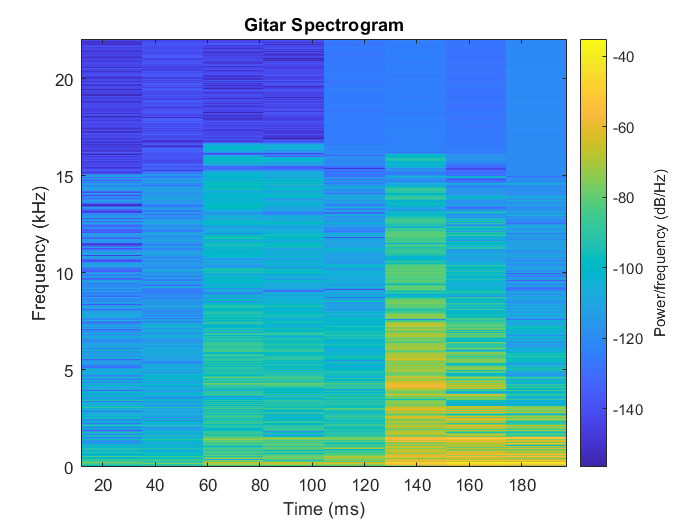


figure()
spectrogram(gitar, window_size, hop_size,window_size,fs,'yaxis');
title('Gitar Spectrogram')

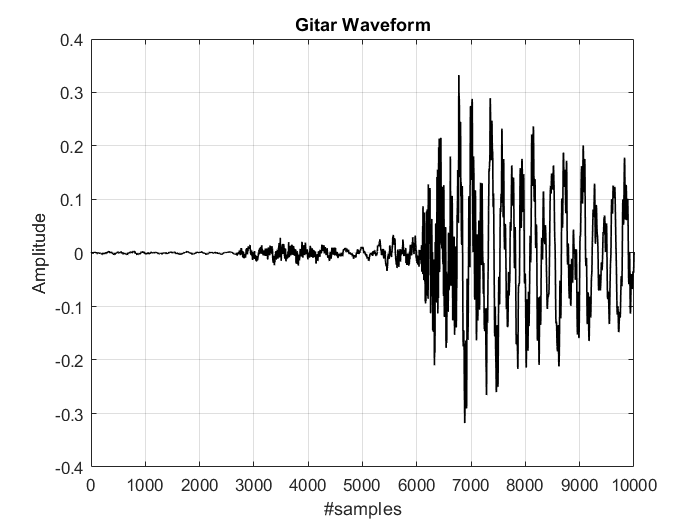

figure()
plot(gitar,'k','LineWidth',1)
xlim([0,n_samples])
xlabel('#samples')
ylabel('Amplitude')
title('Gitar Waveform')
grid on

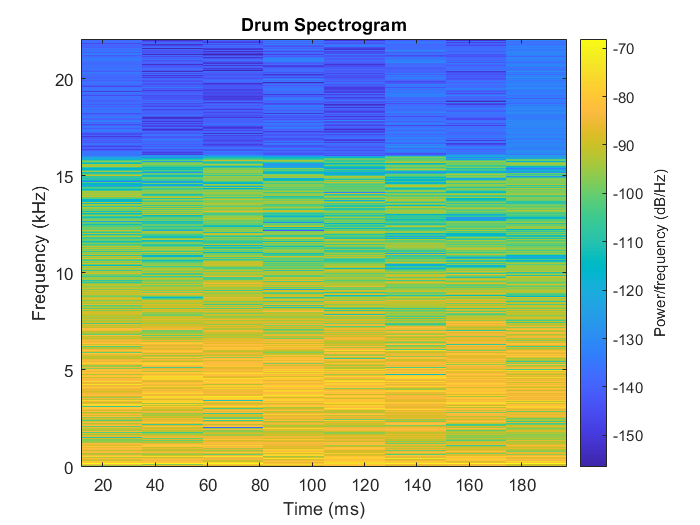


figure()
spectrogram(drum, window_size, hop_size,window_size,fs,'yaxis');
title('Drum Spectrogram')

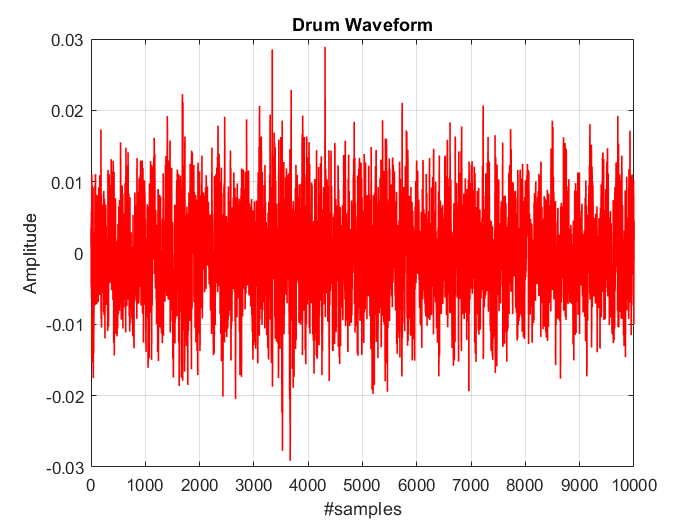

figure()
plot(drum,'r','LineWidth',1)
xlim([0,n_samples])
xlabel('#samples')
ylabel('Amplitude')
title('Drum Waveform')
grid on

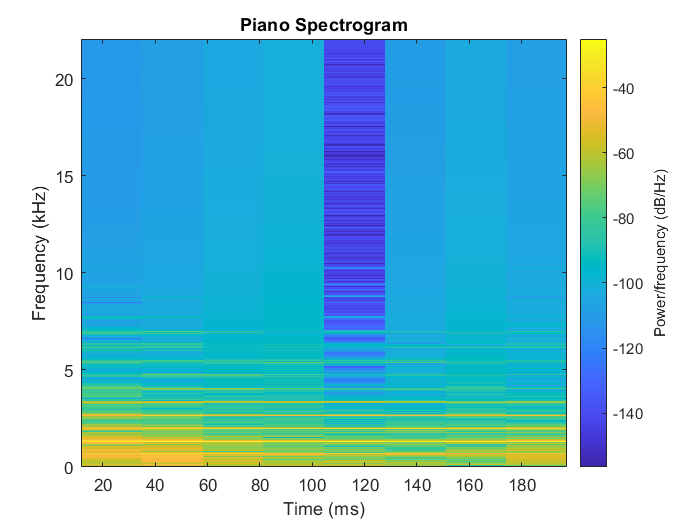


figure()
spectrogram(piano, window_size, hop_size,window_size,fs,'yaxis');
title('Piano Spectrogram')

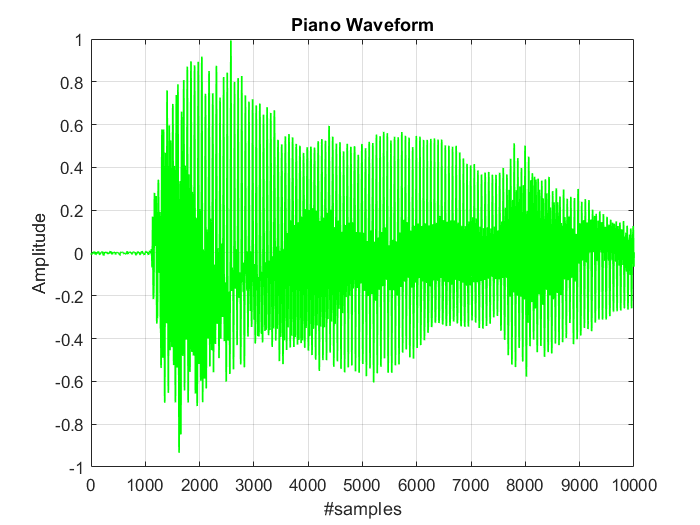

figure()
plot(piano,'g','LineWidth',1)
xlim([0,n_samples])
xlabel('#samples')
ylabel('Amplitude')
title('Piano Waveform')
grid on

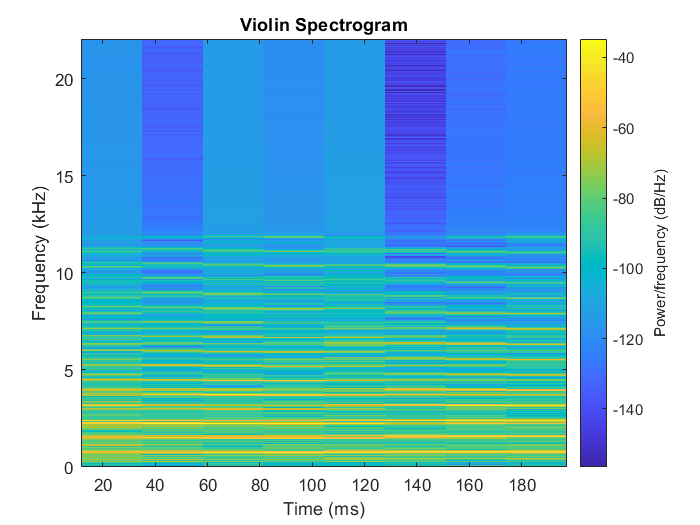


figure()
spectrogram(violin, window_size, hop_size,window_size,fs,'yaxis');
title('Violin Spectrogram')

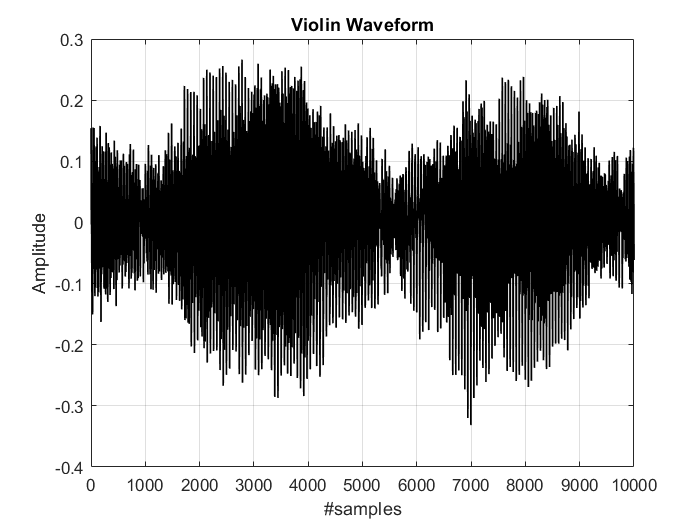

figure()
plot(violin,'k','LineWidth',1)
xlim([0,n_samples])
xlabel('#samples')
ylabel('Amplitude')
title('Violin Waveform')
grid on

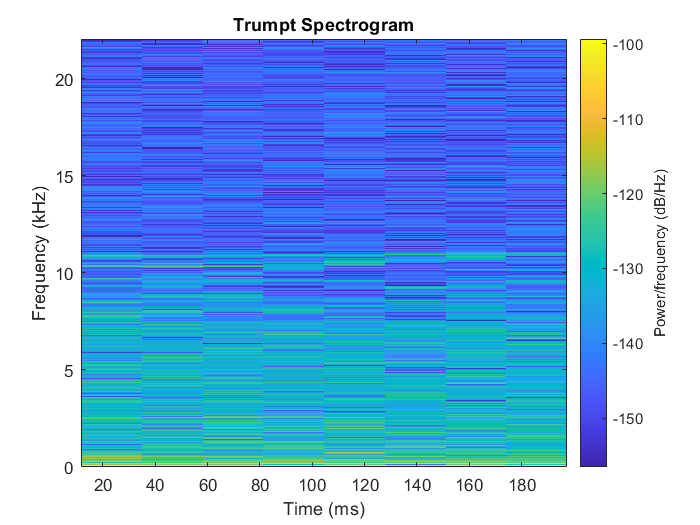


figure()
spectrogram(trumpt, window_size, hop_size,window_size,fs,'yaxis');
title('Trumpt Spectrogram')

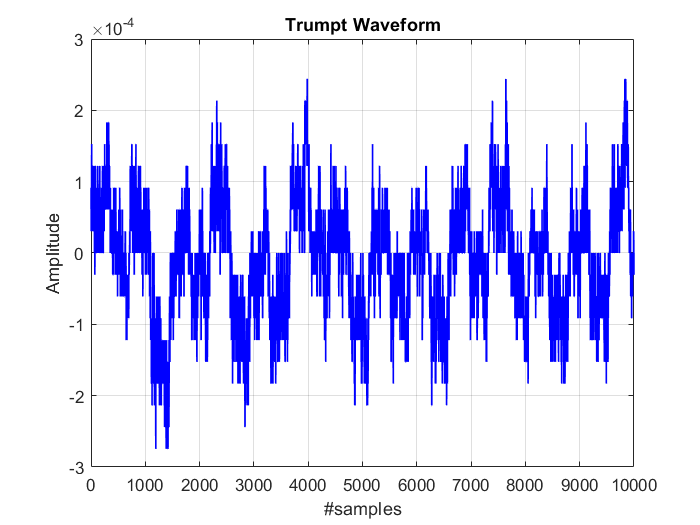

figure()
plot(trumpt,'b','LineWidth',1)
xlim([0,n_samples])
xlabel('#samples')
ylabel('Amplitude')
title('Trumpt Waveform')
grid on